# Multidomain Physical Modeling

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

So far, we've assumed an idealized model of the quadcopter that doesn't take into account many physical design considerations. For example, we are simply setting the value of the thrust force using the speed for a given propeller size. However, real quadcopter rotors cannot instantaneously achieve a target velocity as they are driven by a DC electric motor. 

To improve the accuracy of our models, we need to include the response time and inertia of the system. Next, let's see how to create a physical model of a DC Motor in Simscape™ and control it using pulse-width modulation. 

## **What is Simscape?**

[**Simscape**](https://www.mathworks.com/products/simscape.html) enables us to rapidly create models of physical systems within the Simulink environment. Simulink is a signal-flow (causal) block-diagram environment where each block computes its outputs from its inputs, usually by time-update equations. These functional blocks (transfer functions, gains, filters) encode mathematics to be performed on the numeric input signals to compute numeric output signals. In Simscape, you assemble physical components such as propellers, resistors, and valves into (acausal) networks with physical conserving junctions. Simscape ports carry physical quantities as through and across variables and enforce conservation laws. A Simscape model produces implicit differential-algebraic equations (DAEs) from physical laws (Kirchhoff, Newton, etc) without assigning a computation direction to each component. 

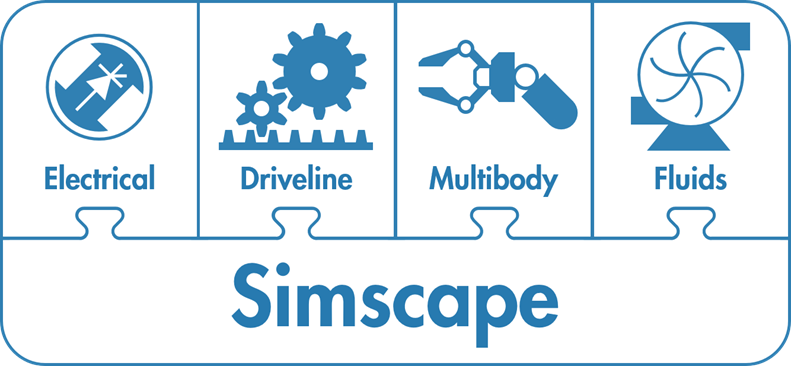

We can model systems such as electric motors, bridge rectifiers, hydraulic actuators, and refrigeration systems, by assembling fundamental components into a schematic with the physical plant in Simscape and the control and logic in Simulink using Simulink-PS and PS-Simulink converters to map between physical quantities and causal signals. 

**Background: **If you are new to Simscape, please complete the following online self-paced courses before attempting this section. 

- [**Simscape Onramp**](https://matlabacademy.mathworks.com/details/simscape-onramp/simscape)

- [**Circuit Simulation Onramp**](https://matlabacademy.mathworks.com/details/circuit-simulation-onramp/circuits)  

Additional courses that may be of interest:

- [**Power Electronics Simulation Onramp**](https://matlabacademy.mathworks.com/details/power-electronics-simulation-onramp/powerelectronics)  Learn the basics of simulating power electronics converters in  Simscape. Model a buck converter at varying levels of model  fidelity—from an idealized behavior to a fully nonlinear model—and  compare their outputs and simulation speeds.

- [**Motor Modeling with Simscape Electrical**](https://matlabacademy.mathworks.com/details/motor-modeling-with-simscape-electrical/otslmmse)  Learn to create a lumped-parameter model of an electric motor using  Simscape Electrical and connect it to a closed-loop controller built  using Motor Control Blockset. Then, incorporate finite element data and  loss modeling to increase the model fidelity.

### **DC Motor Model**

  **Try**. Open the model given here to [learn how to create an electromechanical plant model of a DC motor](https://www.mathworks.com/help/sps/ug/example-modeling-a-dc-motor.html) in Simscape and control its speed using Pulse-Width Modulation (PWM):

openExample('simscapeelectrical/PWMControlledDCMotorExample')
 

Each example will open in a new tab and switch to a new file location. When you are done exploring the example, close the files that were opened, return to this script, and click the "Return Here" button. This will reset your file location to the root folder for this content collection.

### **Propeller Physical Model**

  **Try**. Next, we will begin modeling a more realistic propeller that has inertia (mass). Then we can see how the thrust produced changes with speed. In this first model, the rotation is driven by an ideal angular velocity source rather than a motor. 

- Open `Propeller_Model.slx`, investigate the blocks, and run the model. Observe the output in the scope. What shape is the thrust curve? Why? 

- Change the start time and/or the slope in the ramp block. Run the model and observe the output in the scope.

- How would you change the model to output the rotational speed in rpm rather than rad/s?

- What is the impact of changing the propeller diameter? Or the mass? 

open("Propeller_Model_Soln.slx")
 

 **Pro-tip. **Remember that you can rescale the axis on a [Scope block](https://www.mathworks.com/help/simulink/slref/scope.html) output to show the full range of values using the autoscaling options.

 **Note: **The Aerodynamic Propeller block uses rotation speed in rad/s and the propeller diameter rather than the rotations per minute and radius used in the earlier scripts and models. With a 0.24 m diameter propeller, thrust on the scale of Newtons is created with a thrust coefficient on the scale of $k_T\times 10^6$ from the Quadcopter Basics model. 

### **A Current-Controlled Propeller Model**

In the next model, we attach a current-controlled DC motor to a single propeller and implement a feedback control loop to achieve the required speeds. Open `Propeller_Ref_Speed.slx` and run the model. Observe the output in the scope.

open("Propeller_Ref_Speed_Soln.slx")
 

Using this approach, we can now model how the thrust produced changes with the current drawn by the motor. Design engineers can use this information to size the components correctly. This model also estimates the power draw, which will inform the battery sizing and the range estimation.

For example, in the above model, each quadcopter propeller motor draws approximately 20 amps of current at 14V. As there are four propellers on a quadcopter, the power draw is four times as much, leading to a total current draw of around 80 amps at the highest rotor velocity. This is very high for most applications. The design would probably need to be modified if the quadcopter is to operate safely for long periods of time.

  **Try**. 

- Change the ramp slope and ramp start values using the sliders. What impact does that have on the current, torque, and thrust?

- By comparing the current plot and the differences between the reference speed and motor speed, can you identify how this is different from the ideal torque model in the previous propeller model?

- Change the voltage in the Voltage Source block . What impact does that have on the current, torque, and thrust?

- Change the propeller diameter, thrust coefficient and/or power coefficient in the Aerodynamic Propeller block: 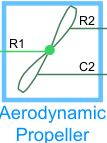

- Change the motor parameters or controller parameters in the `InitFcn` for the model. You can locate them in the Model Settings dropdown in the Tool Strip > Model Properties > Callbacks > InitFcn.  

- Identify the mechanical and electrical Simscape blocks and the Simulink blocks. Where are there conversions between energy states and signals? 

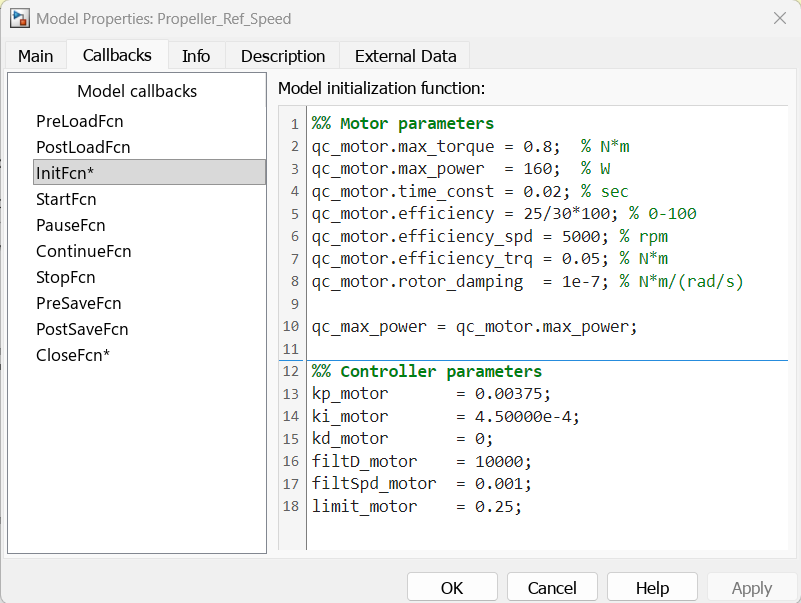

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

## Local Helper Functions

function ReturnHere() %#ok<DEFNU>
curloc = matlab.desktop.editor.getActiveFilename;
if contains(curloc,"Scripts")
    rootdir = extractBefore(curloc,filesep+"Scripts");
elseif contains(curloc,"InstructorResources")
    rootdir = extractBefore(curloc,filesep+"InstructorResources");
else
    error("Unexpected location: " + curloc)
end
cd(rootdir)
end